# **Tutorial 4**: a spacecraft with 2 symmetrical rotating solar arrays defined by a NASTRAN model ( $\approx 1\;mn$ run).

*by D. Alazard and F. Sanfedino - ISAE-SUPAERO*

## 1. Description

This tutorial reconsiders the same example already addressed in the [tutorial 2](matlab:open('../Tutorial2/tutorial2.html')) but the models $[\mathbf D_{A_i}^{\mathcal{A}_i}]_{\mathcal R_{a_i}}(\mathrm s)$, ($i=1,2$) of 2 the rotating solar flexible solar arrays are now defined by:

- a` .f06` file provided be a Nastran analysis assuming that the reference point for this analysis of the solar array $\mathcal A_i$ is the connection point $P_i$ with the main body $\mathcal B$,

- a revolue joint at the point $P_i$.

## 2. NASTRAN interface

The simplest interface with NASTRAN is the block `1 port Nastran body` of the **SDTlib/**`6 dof bodies` sub-library. This bloc requires only the name of `.f06` file, the number of flexible modes (ordered by increasing frequency) to be taken into the block and the common damping ratio for all the considered flexible modes.

In addition, the user can specify a relative uncertainty on the frequency of each of the considered flexible modes.

The dialog box of this block is depicted in the following figure.

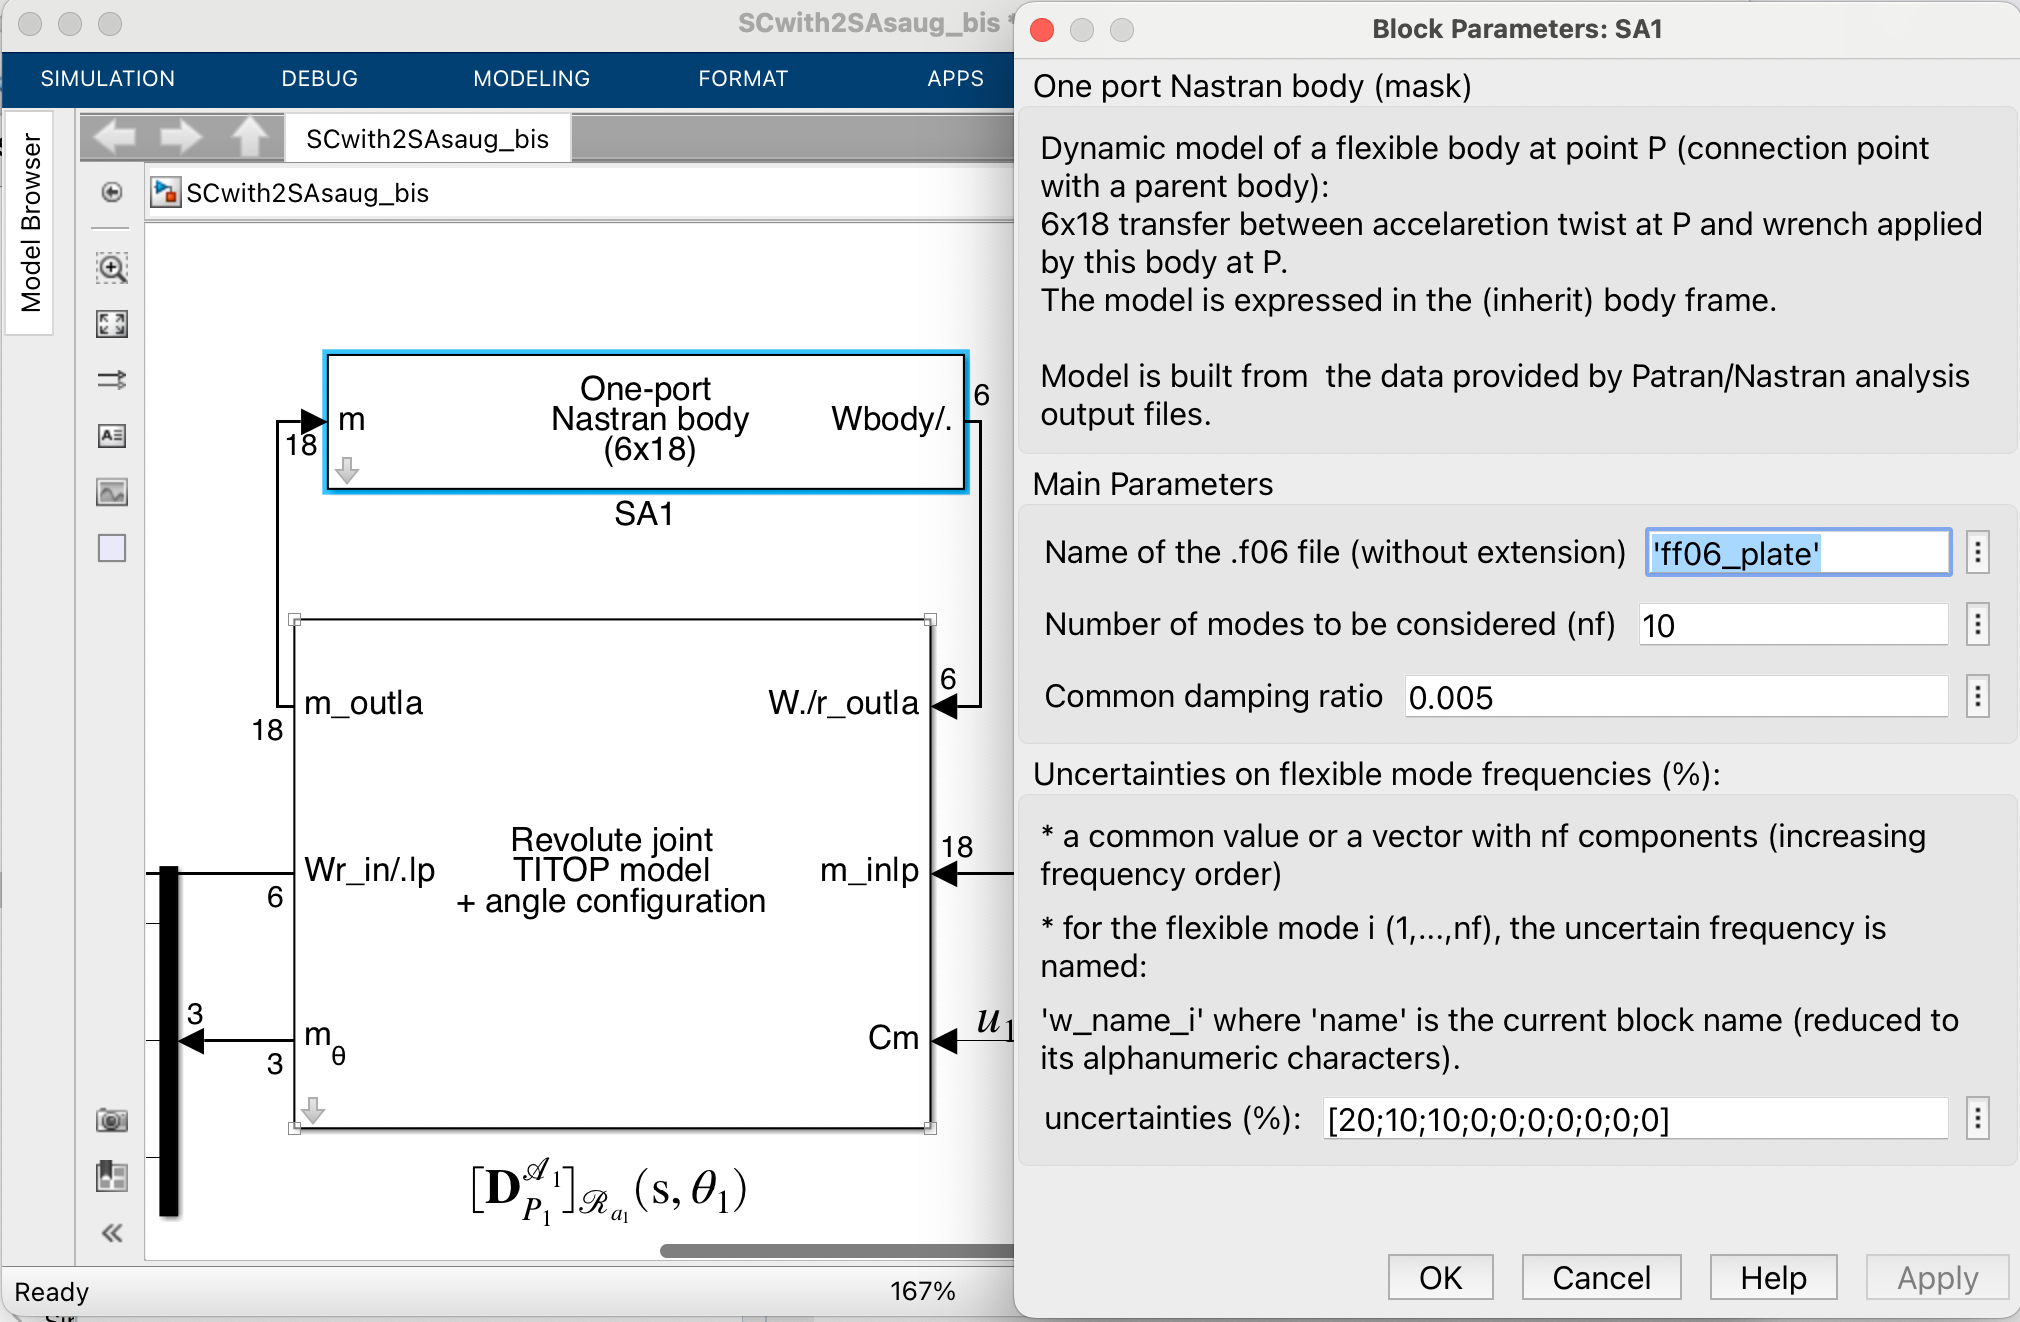

The file  `ff06_plate.f06` specified in the dialog box is proposed as an example. It corresponds to a square plate of aluminium ( $1\times 1\times 0.01\,(m)$ )  and is available in `NASTRANfiles `sub-library available with the `SDTlib. `$20\%$, $10\%$ and $10\%$ of relative variations are taken into account on the flexible 1, 2 and 3, respectively, among the 10 flexibles modes extracted from the `.f06` file. 

The reader is advised to read the inline help available in the dialog box (internet connection required), also available by:

web Doc1PortNastranBody.html -new

## 3. Revolute joint

The revolute joint is modeled thanks to the block `Revolute joint + configuration `on the `SDTlib/6 dof mechanisms` sub-library.

According to the dialog box depicted in the following Figure, this block requires:

- the direction of the revolute axis in the inherit (local) frame, 

- the output shat inertia (one can put a very small value when this data is unknown),

- the angular configuration of the joint (the other block, named `Revolute joint `in the` 6 dof mechanisms` sub-library`, `assumes small angular variations around $0$).

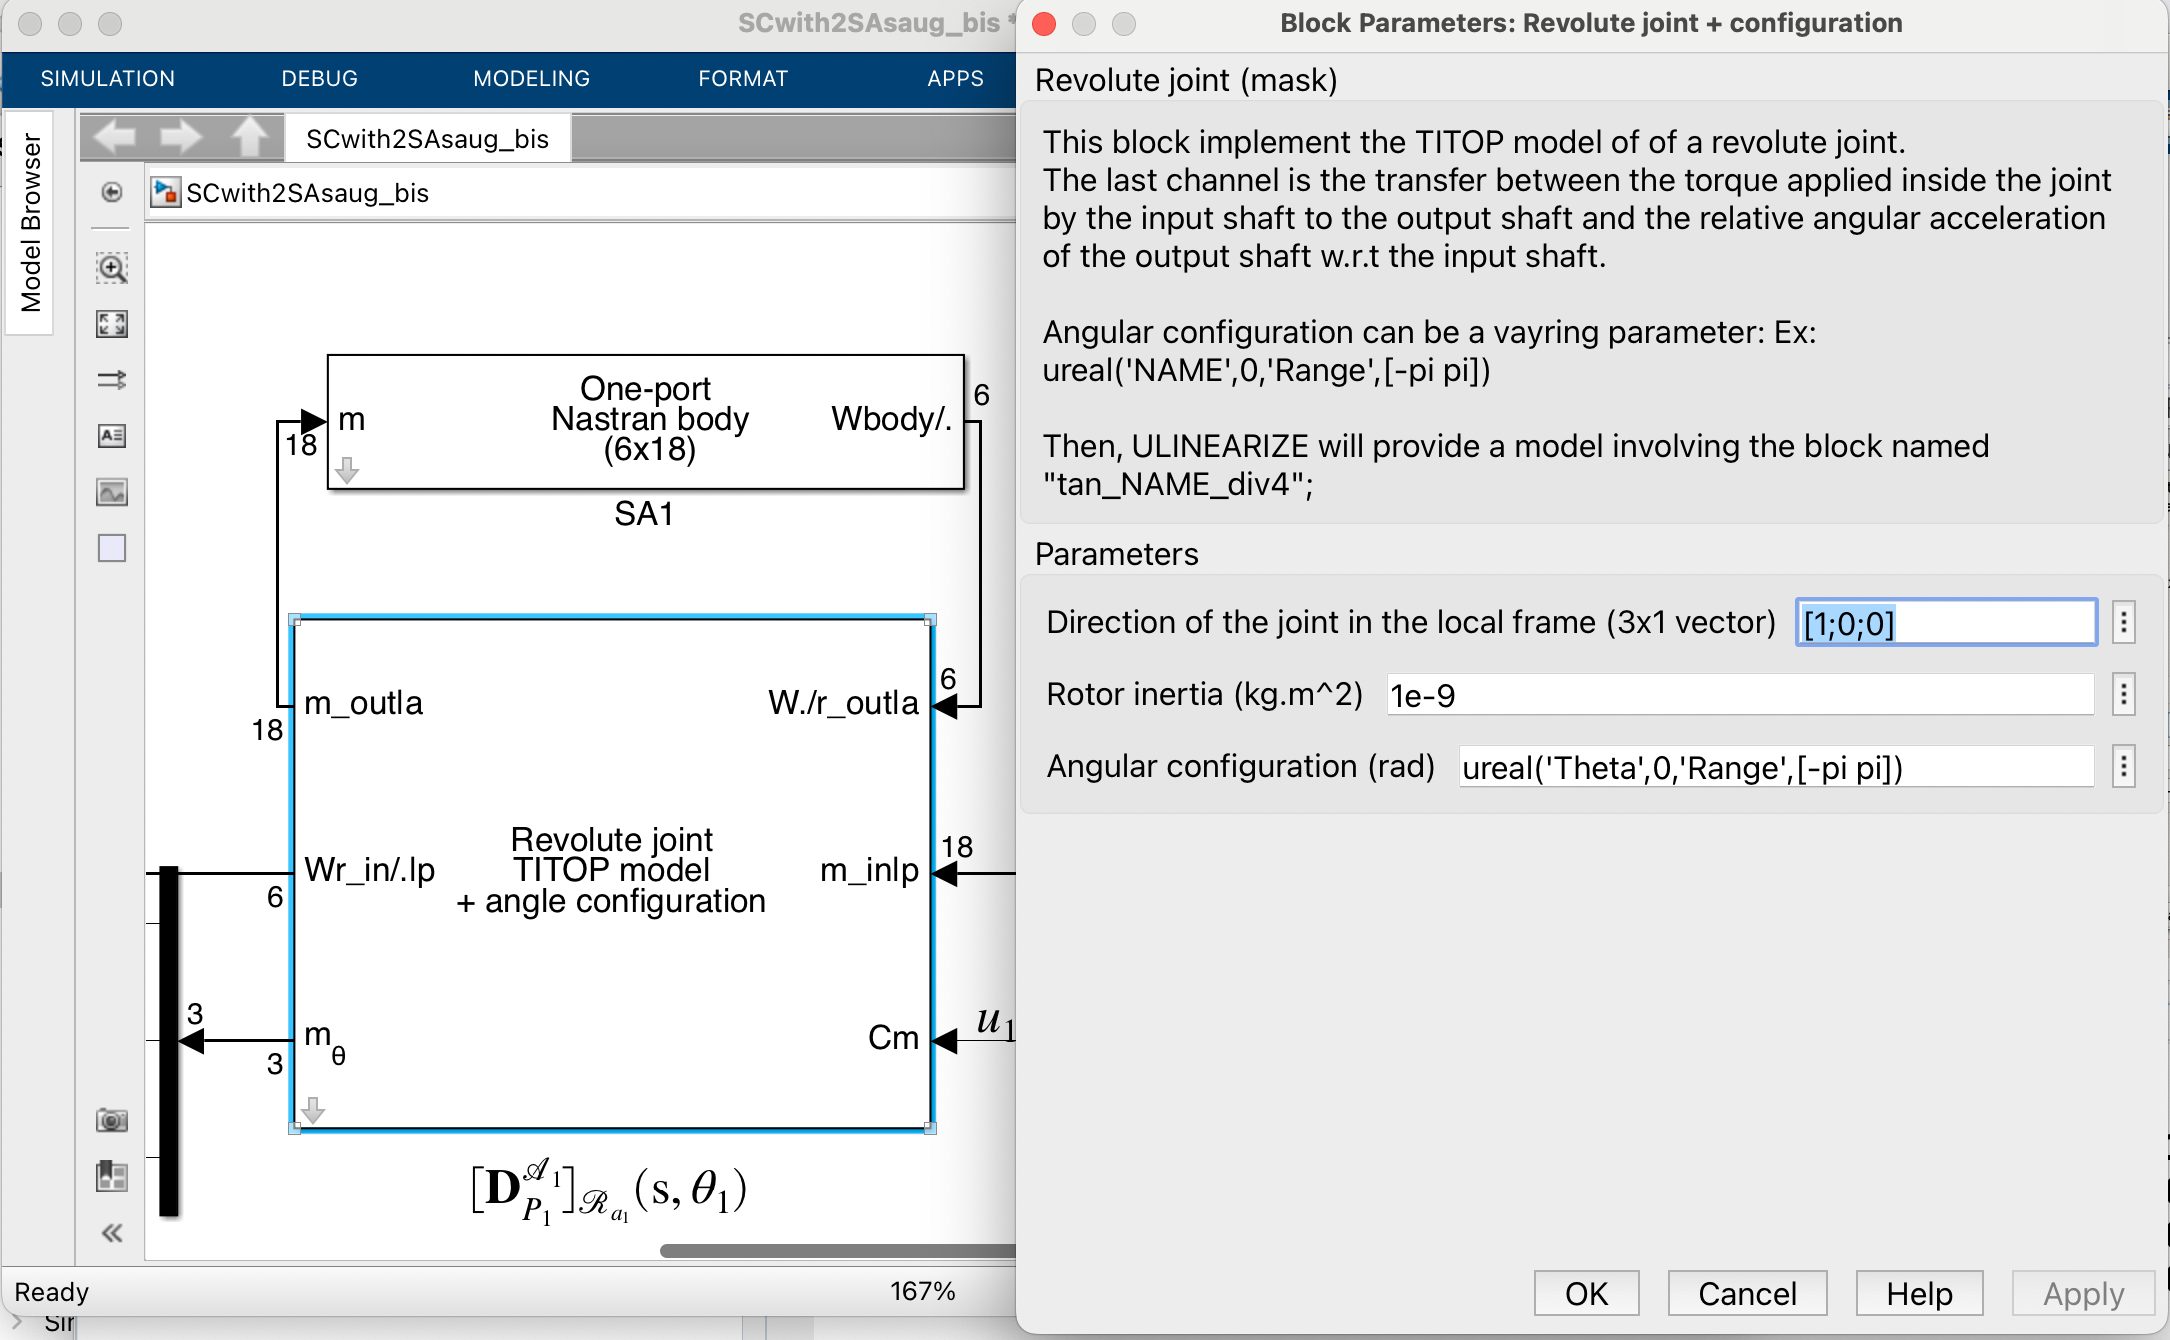

See also:

web DocRevoluteJoint_configuration.html -new

## 3. The whole  $6\times 8$ dynamic model

The whole model is then described by the following SIMULINK file `SCwith2SAsaug_bis.slx`:

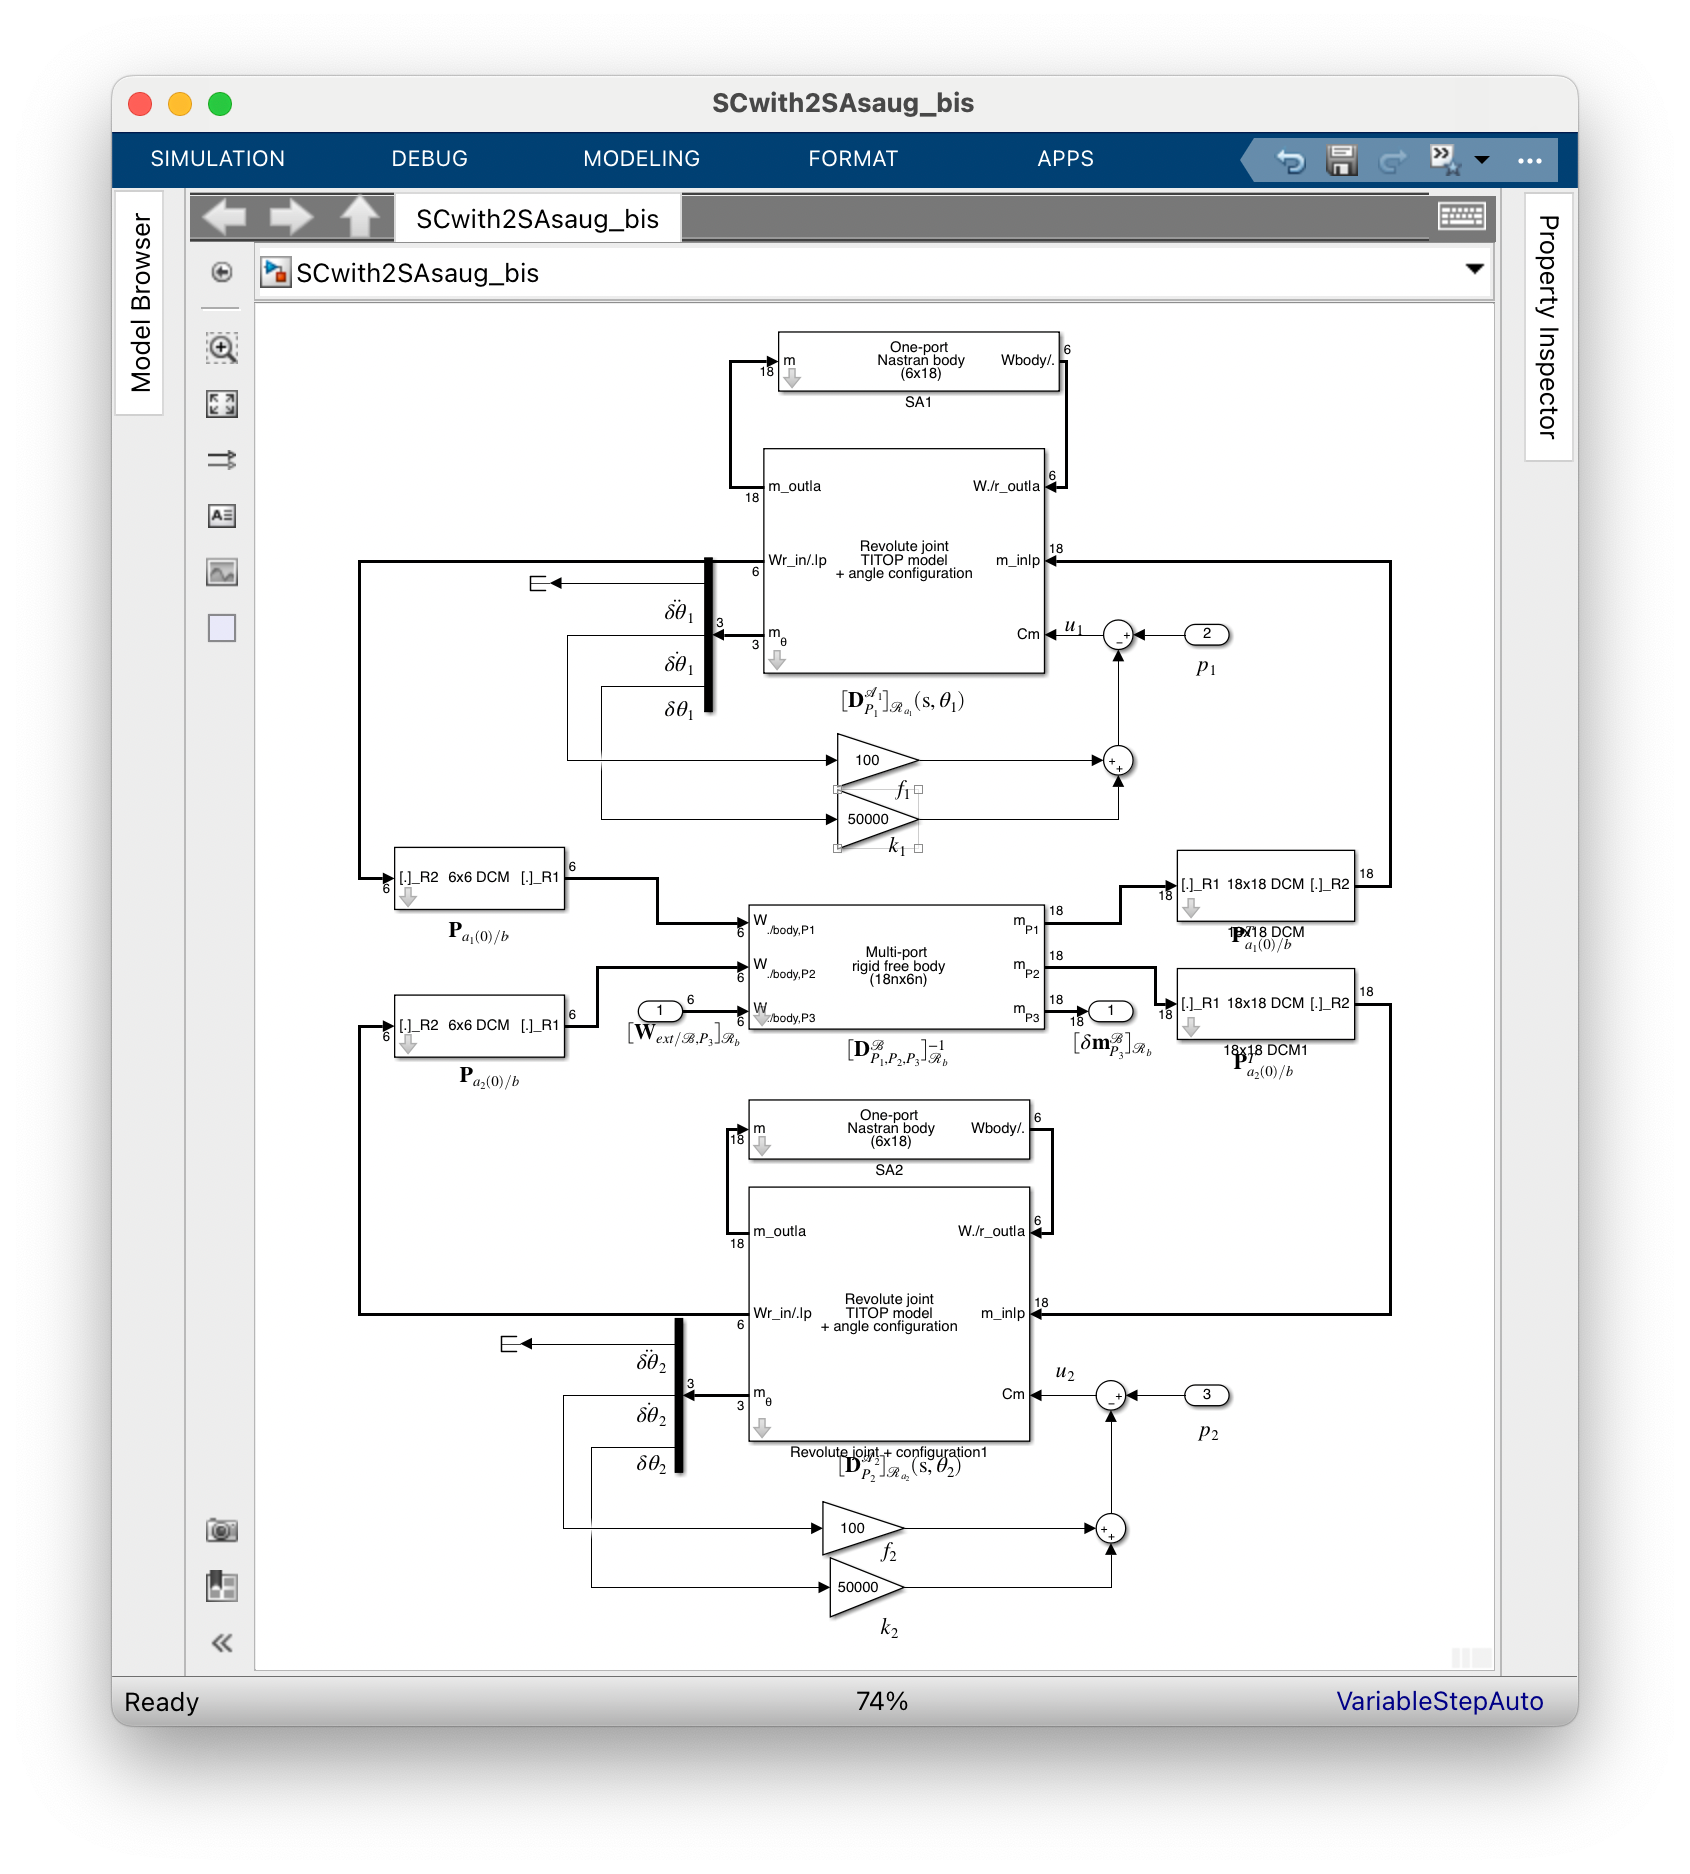

SCwith2SAsaug_bis                      % the SIMULINK lile of the model
Gu=ulinearize('SCwith2SAsaug_bis')

Gu =

  Uncertain continuous-time state-space model with 18 outputs, 8 inputs, 56 states.
  The model uncertainty consists of the following blocks:
    tan_Theta_div4: Uncertain real, nominal = 0, range = [-1,1], 32 occurrences
    w_SA1_1: Uncertain real, nominal = 10.2, variability = [-20,20]%, 2 occurrences
    w_SA1_2: Uncertain real, nominal = 17.3, variability = [-10,10]%, 2 occurrences
    w_SA1_3: Uncertain real, nominal = 67.4, variability = [-10,10]%, 2 occurrences
    w_SA2_1: Uncertain real, nominal = 10.2, variability = [-20,20]%, 2 occurrences
    w_SA2_2: Uncertain real, nominal = 17.3, variability = [-10,10]%, 2 occurrences
    w_SA2_3: Uncertain real, nominal = 67.4, variability = [-10,10]%, 2 occurrences

Type "Gu.NominalValue" to see the nominal value, "get(Gu)" to see all properties, and "Gu.Uncertainty" to interact with the uncertain elements.



As in [tutorial 2](matlab:open('../Tutorial2/tutorial2.html')), one can check that the model have 8 inputs:

- the external wrench $[\mathbf W_{ext/\mathcal B,B}]_{\mathcal R_b}$ (6 components)

- $p_1$ the torque disturbance inside the revolute joint of $\mathcal A_1$,

- $p_2$ the torque disturbance inside the revolute joint of $\mathcal A_2$,

18 outputs:  the motion vector of point $B$ $[\delta\mathbf m^\mathcal{SC}_B]_{\mathcal R_b}$ (18 components),

but 56 states: 28 modes (10 flexible modes + 1 revolute joint mode per appendage + 6 rigid modes).

This model depends on :

- the uncertain parameter $\sigma_4=\tan\frac{\theta}{4}$ (`tan_Theta_div4`) with 32 occurences.

- the uncertainties on the first 3 frequencies of the 2 solar panels (`w_SAi_j, i=1,2, j=1,2,3`).

## 4. Parametric association

The model `Gu `is fully compatible with the `MATLAB Robust Control Toolbox``. `It is thus possible to associate the various uncertain parameters or to specify new variations using the function `ususbs`. 

As specified in the dialog box of the `1 port Nastran body`, the uncertainties correspond to independant **manufacturing uncertainties** on the flexible mode frequencies of the 2 solar pannels. At preliminary design phase, it is better to specify `design uncertainties`. That is to say, the 2 solar pannels are identical but there are some uncertainties on the solar pannel flexible modes. That can be done by associating the uncertain parameters of the model `Gu` to new design uncertain parameters which are the same for the 2 solar panels. The syntax is the following:

w_SA_1=ureal('w_SA_1',10.2,'percent',20);
w_SA_2=ureal('w_SA_2',17.3,'percent',20);
w_SA_3=ureal('w_SA_3',67.4,'percent',20);
Gu_sym=usubs(Gu,'w_SA1_1',w_SA_1,'w_SA2_1',w_SA_1,...
                'w_SA1_2',w_SA_2,'w_SA2_2',w_SA_2,...
                'w_SA1_3',w_SA_3,'w_SA2_3',w_SA_3)

Gu_sym =

  Uncertain continuous-time state-space model with 18 outputs, 8 inputs, 56 states.
  The model uncertainty consists of the following blocks:
    tan_Theta_div4: Uncertain real, nominal = 0, range = [-1,1], 32 occurrences
    w_SA_1: Uncertain real, nominal = 10.2, variability = [-20,20]%, 4 occurrences
    w_SA_2: Uncertain real, nominal = 17.3, variability = [-20,20]%, 4 occurrences
    w_SA_3: Uncertain real, nominal = 67.4, variability = [-20,20]%, 4 occurrences

Type "Gu_sym.NominalValue" to see the nominal value, "get(Gu_sym)" to see all properties, and "Gu_sym.Uncertainty" to interact with the uncertain elements.



In this new model the 2 solar pannels are identical for any values of the 3 parameters `w_SA_1, w_SA_2, w_SA_3`.

## 5. Analyses

As in [tutorial 2](matlab:open('../Tutorial2/tutorial2.html')), the same kind of analyses can be now performed on this new model, for instance  the frequency-domain response (*Bode* magnitude) of the $3\times 3$ transfer between the torque applied to the spacecraft at $B$ and its attitude:

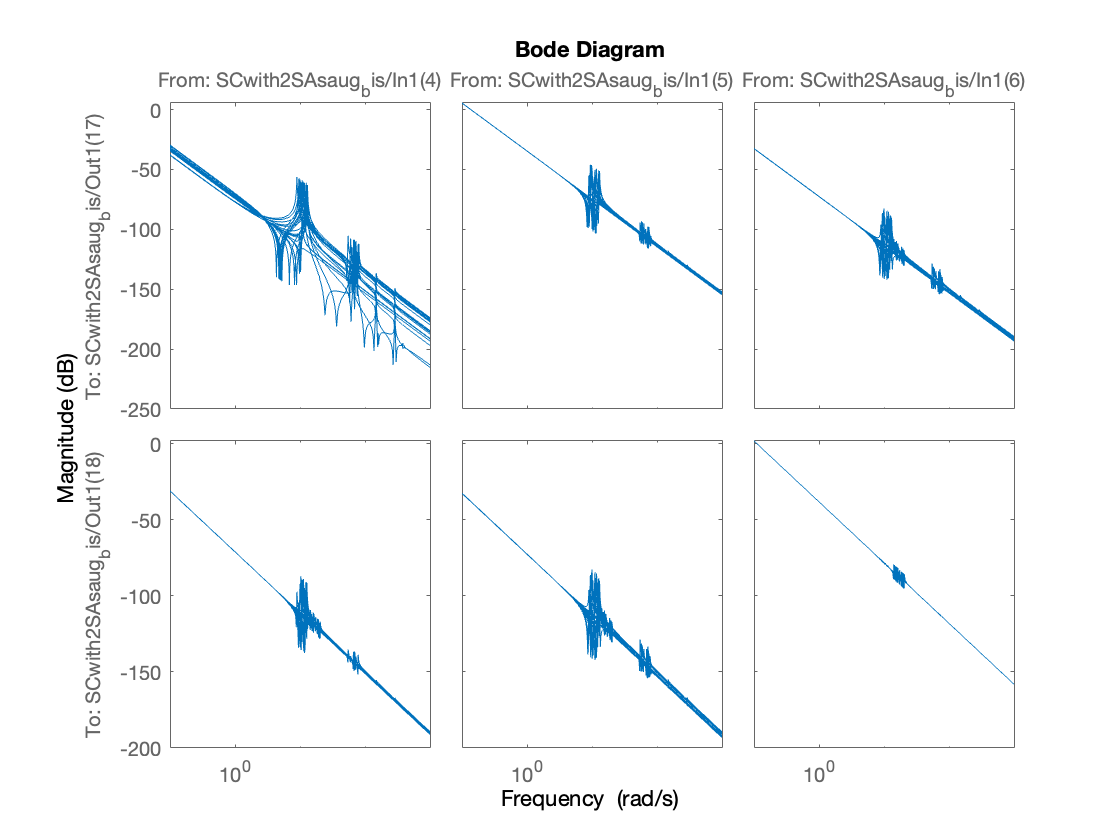

figure
bodemag(Gu_sym(17:18,4:6),{0.1 1000})

## 6. Remarks

- the block `1 Port Nastran body `is the simplest interface between the` SDTlib` and `NASTRAN`. If the user wants to build the model of an array of solar pannels or to model some external loads (wrenches) at some particular points $C_i$ of the solar pannel, a muti-port model is required and the user is advised to use the block  `N Ports Nastran body `(see tutorial 7: [***the cantilevered plate dynamics studied with SDTlib block NINOP Nastran body***](matlab:open('../Tutorial7/tutorial7.html'))`)`,

- it is also possible to use the `multi-port flexible plate `of the sub-library: `6 dof bodies `to model the solar array (see tutorial 8: [***a spacecraft with 2 symmetrical rotating solar arrays defined by a generic plate model***](matlab:open('../Tutorial8/tutorial8.html'))).